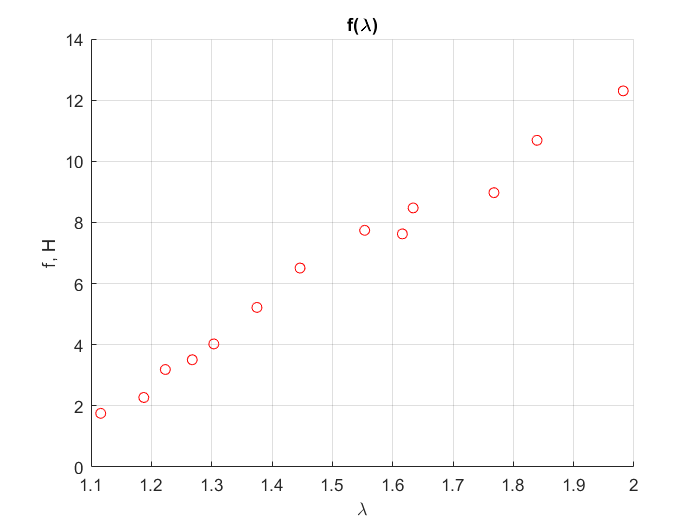

file = importdata('251.xlsx');
y = file.data(5:1:17, 3);
x = file.data(5:1:17, 5);

sizex = size(x, 1);
sizey = size(y, 1);

fg1 = figure;

%plot(x,y,'or')
hold on;
%x2 = linspace(min(x),max(x),100);
%y2 = spline(x,y,x2); % кажется так
plot(x, y, 'or');
hold on;

x1 = x(1:sizex - 1:sizex, :);
y1 = y(1:sizey - 1:sizey);

xmin = (min(x));
ymin = (min(y));

xmax = (max(x));
ymax = (max(y));

x2 = [xmin, xmax];
y2 = [ymin, ymax];

%plot(y2, x2, 'b');

grid on;
%legend('\lambda(F)');
xlabel('\lambda');
ylabel('f, H');
title('f(\lambda)');
%text(27, 0.75,'Даниил Талашкевич, Б01-009');
saveas(fg1, 'graph3', 'png');